# 4-1. あらゆる方向からのラドン変換を考える

前章までで、一方向でのラドン変換を実装しました。

しかし、ラドン変換は実行する方向によってその結果が異なります。

そこで、今回はモデルを360°全方向からラドン変換を行う場合を考えてみます。

2章の断面積計算で台形を使った場合はこのまま進んでください。

三角形を使った人は4-2を読んでください。

## 1. ラドン変換を行う方向のデータについて

全方向からのラドン変換としているが、実際はディジタルデータのため、有限個の *n *方向でラドン変換を行います。

このときの方向を決定するデータとして、原点を中心とする単位球表面上の、一様分布に従う *n *個の点を使います。

（参考：https://reference.wolfram.com/language/ref/SpherePoints.html）

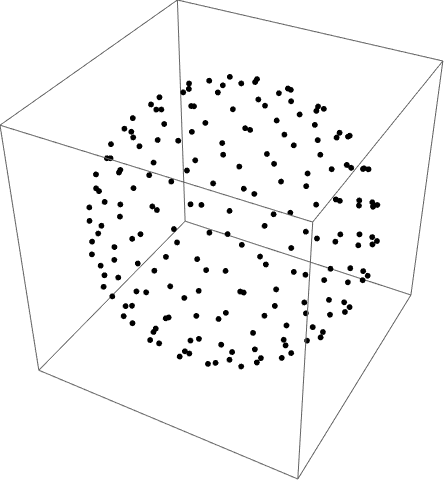

上図のような点群データをラドン変換を行う方向として使えば、誤差はあるが全方位をカバーできます。

このときの点群データは事前に計算したものが準備されているのでデータを読み込んで使います。

この点群データのことを以下視点データと呼びます。

sp点数.mat で保存されているのでワークスペースに追加してみます。

%視点数
v = 60;
%視点の読み込み
Path = sprintf('prjDirections/sp%d', v);
sp = load(Path);
Vertex1 = sp.Expression1;

3行目の sprintf 関数が用いられている理由は各自調べてみてください。

上手く実装が出来ているとワークスペースで以下のように点群データを確認できると思います。

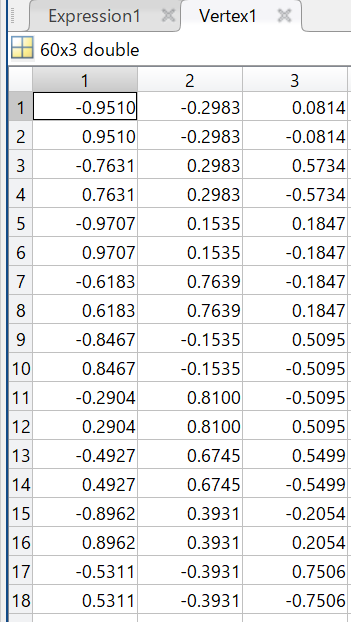

注意点として、なにもしないと現在開いているフォルダ内のファイルしか使うことができません。

そこで、他のフォルダ内のデータを使いたい場合、以下のように目的のファイルが入っているフォルダをパスに追加しておきましょう。自分で作った関数などについても同様です。

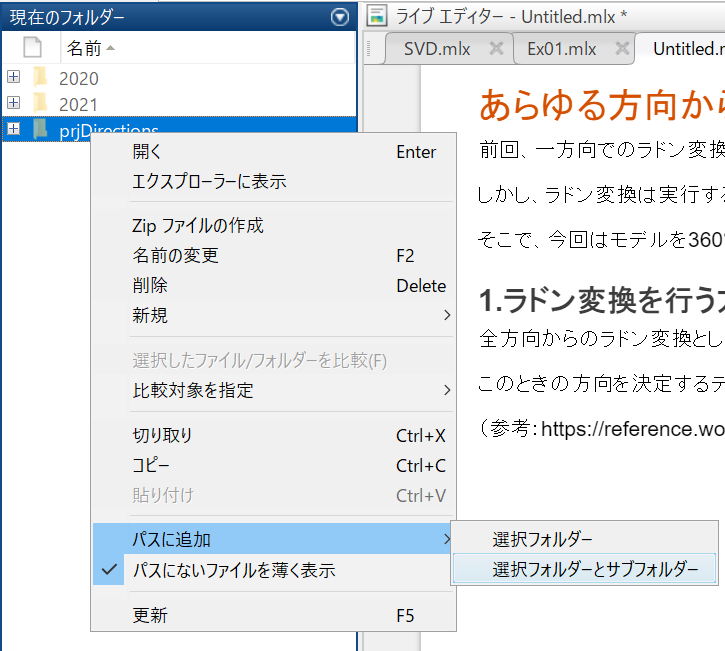

具体的にデータを見てみましょう。

% Vertex1の最初の5行を見る
Vertex1(1:5,:)

ans =    -0.9510   -0.2983    0.0814
    0.9510   -0.2983   -0.0814
   -0.7631    0.2983    0.5734
    0.7631    0.2983   -0.5734
   -0.9707    0.1535    0.1847


Vertex1の各行はそれぞれの点の x,y,z 座標を表現しています。

1行目より、点1は (x,y,z) = (-0.9510, -0.2983, 0.0814) にあることがわかります。

このベクトルをラドン変換の軸として扱うことで全方向からのラドン変換を行います。

ここで、モデルの断面積を台形を用いて求める場合、以下のことが必要になります。

- 全てのパッチがラドン変換の軸と交差していない

- ラドン変換を行う範囲にすべてのパッチが存在する

これらを実現するために、以下の手順をラドン変換をする前に行います。

- モデルの中心座標と半径を計算する

- ラドン変換の軸とモデルの中心との距離が、半径よりも大きくなるようにモデルを移動させる

- 視点データで与えられる軸が x 軸と一致するようにモデルを中心とした回転を行う

## 2. モデルの中心座標と半径を計算する

検索したいモデルに、モデルの中心座標がパラメータとして与えられているとは限りません。

そのため、頂点データからモデルの中心座標を計算します。

モデルの半径は、モデルの中心座標を中心とする円を考えるときモデル全体が円に収まるときの長さとします。

get_radius.m を書き換えて、モデルの中心座標と半径を返す関数を完成させてください。

このとき、モデルがピッタリ収まるのではなく少し余裕があるといいです。

file_path = "sampleModel.stl";
TR = stlread(file_path);

[center,radius] = get_radius(TR.Points)

center =   111.7057   26.4681   89.5701


radius = 90

テストコード

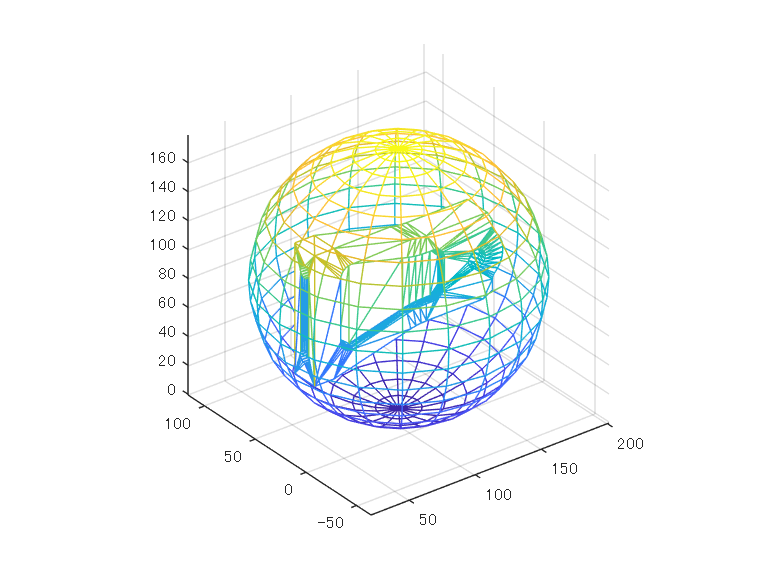

% 球のデータ
[x,y,z] = sphere;
figure
trimesh(TR)
hold on
% モデルの中心座標を中心とするモデルの半径を半径とする球
mesh(x*radius+center(1),y*radius+center(2),z*radius+center(3),'FaceColor','none')
hold off
axis("equal")

上の図でモデルが球に収まっていれば問題なく計算できています。

## 3. モデルの移動

2節で求めた中心座標と半径を使ってモデルを移動させます。

2節で出力した画像から、sampleModel2.stl ではモデルが x 軸、y 軸、z 軸でそれぞれ交わっていることがわかります。

このような場合、台形を使って計算する方法でのラドン変換は難しいです。

そこで、モデルを移動させることで軸と交わらないようすることを考えます。

3章で実装した x 軸を軸としたラドン変換が正しく行われるようにモデルを移動させてみましょう。

tol = 3e+4;
d = [radius,radius,radius]-center % 移動させる値を自分で入力

d =   -21.7057   63.5319    0.4299


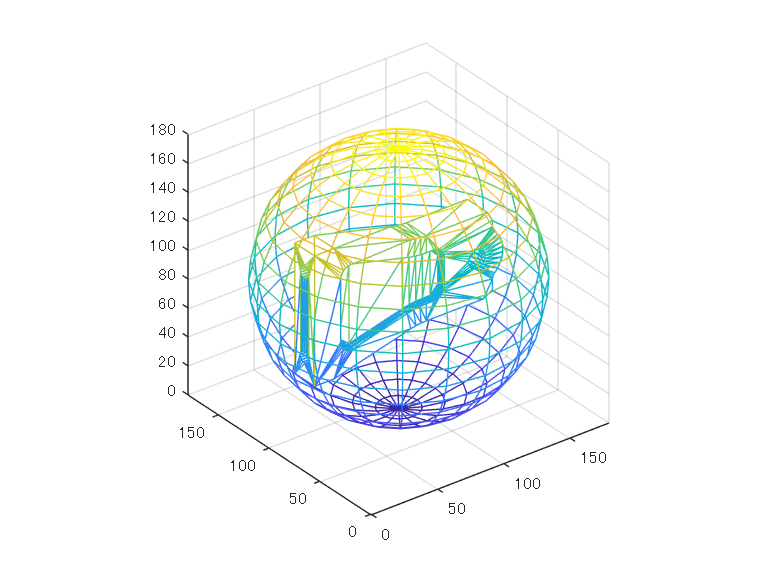


p = TR.Points;
moved_p = p + d;


% 球のデータ
[x,y,z] = sphere;
figure;
trimesh(TR.ConnectivityList, moved_p(:,1), moved_p(:,2), moved_p(:,3))
hold on
% モデルの中心座標を中心とするモデルの半径を半径とする球
mesh(x*radius+radius,y*radius+radius,z*radius+radius,'FaceColor','none')
hold off
axis("equal")

## 4. モデルの回転

1節で述べた視点データのそれぞれを軸としたラドン変換を考えます。

これは、視点データのベクトルが x 軸と平行になるような回転をモデルに対して行い、その後 x 軸を軸としたラドン変換を行う場合と等価です。

そのため、この節ではモデルの回転について考えます。 

### 4-1. 座標の回転

始めに、点座標を回転させる方法を考えてみましょう。

1節で与えられた視点データは、直交座標系の x,y,z 座標で与えられていました。

なので、直交座標系を与えられた時の回転を考えます。

直交座標系は、 [cart2sph](https://jp.mathworks.com/help/matlab/ref/cart2sph.html) 関数を使うと、以下のように極座標系に変換することができます。

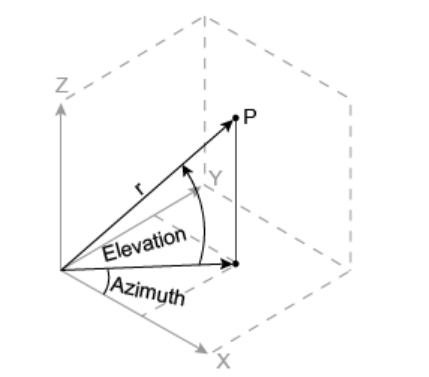

図から、直交座標は z 軸回転の角度 Azimuth （方位角）、y 軸回転の角度 Elevation（仰角）と原点からの距離 r で表すことができます。

今回のように視点情報が直交座標系で用意されているときは、このように、極座標変換によって直交座標を角度情報に変換することで回転を行います。

このとき、右回りの回転が正となる点に注意してください。

実際に、直交座標系 (x,y,z) =  (1,1,1) を極座標変換してみると

[az,el,r] = cart2sph(1,1,1)

az = 0.7854

el = 0.6155

r = 1.7321

これより、直交座標系 (x,y,z) =  (1,1,1) はベクトル x 軸（例として (1,0,0)とする） を z 軸回りに 0.7854、y 軸回りに -0.6155 だけ回転させ、1.7321 倍したものと同じとなります。

今回のアルゴリズムでは、「任意の視点方向を x 軸方向に向ける回転」を実装することを考えます。

このとき「任意の視点方向を x 軸方向に向ける回転」は「x 軸方向を任意の視点方向に向ける回転」の逆変換として考えることができます。

そのため、任意の視点 (x,y,z) としたときの方位角、仰角が az 、el だったとすれば、(x,y,z) を y 軸回りに el 、z 軸回りに -az 回転させることで、(x,y,z) は x 軸上の点になることが分かります。

#### 4-1-1. 回転軸の順序について

4-1章で、今回のアルゴリズムでは、z 軸回りの回転と y 軸回りの回転の2つの軸での回転を使うことを示しました。

ここでは、回転させる軸の順番について考えます。

下図では、y 軸上のベクトルを x 軸回りに90°、y 軸回りに40°回転させる場合の2通りの例を示します。

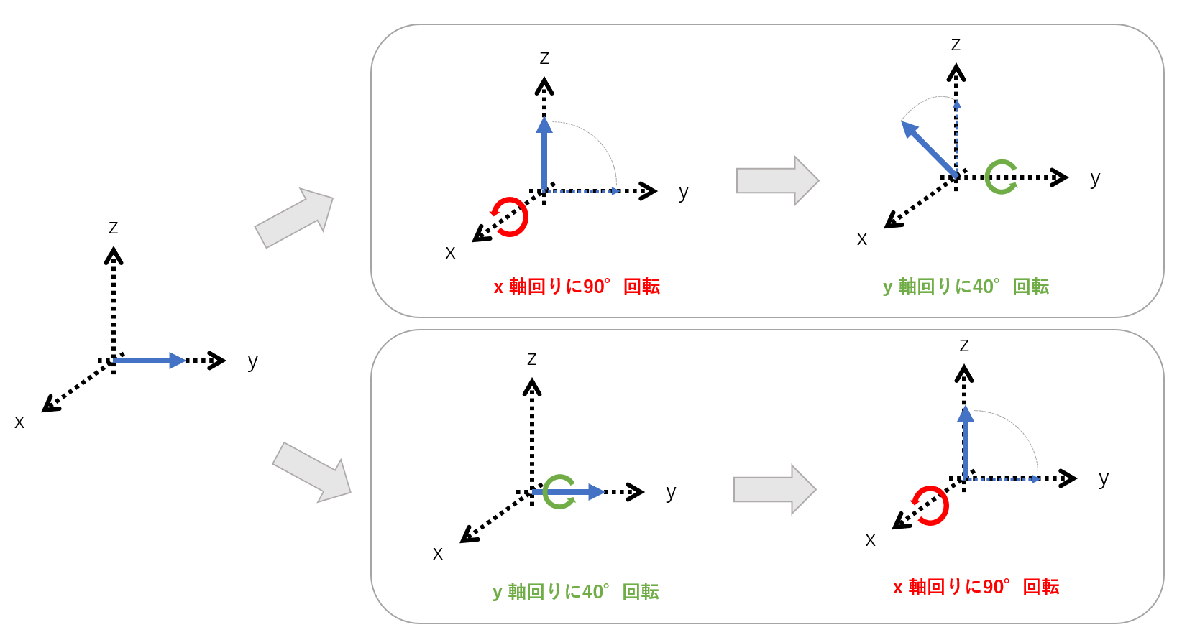

図から分かる通り、3次元の回転では、それぞれの軸で同じ角度回転させたとしても、回転させる順序が違えば回転全体の結果が変わってしまいます。

このことに注意して考えると、cart2sph 関数は、z 軸、y 軸の順番で回転を行って「x 軸方向を任意の視点方向に向ける回転」の角度を求めます。

よって、その逆変換である「任意の視点方向を x 軸方向に向ける回転」を正しく実装するためには y 軸、z 軸の順番で回転を行う必要があることがわかります。

実際に回転させる行列を作ってみます。

rotation.m を書き換えて、方位角と仰角を用いて任意の点を回転できるようにしてください。

下のコードのように任意の直交座標（この場合は(x,y,z) =  (0.8190,0.5670,0.0875) ）を視点情報とする場合、極座標変換をして得た方位角と仰角でベクトル (x,y,z) =  (0.8190,0.5670,0.0875) を回転させるとx軸方向の単位ベクトルに戻るはずです。


[az,el,~] = cart2sph(0.8190,0.5670,0.0875);
pp = rotation_point([0.8190,0.5670,0.0875],-az,-el)

pp =     1.0000         0   -0.0000


プログラムが正しい場合、上に (1,0,0) と表示されます。

テストコード

tol = 1e-4;
% 別の点
[az,el,~] = cart2sph(0.6651,-0.7395,0.1037);
pp = rotation_point([0.6651,-0.7395,0.1037],-az,-el);
assert(all(abs(pp-[1,0,0]) < tol))
% 別の点
[az,el,~] = cart2sph(0.2449,0.4809,0.8419);
pp = rotation_point([0.2449,0.4809,0.8419],-az,-el);
assert(all(abs(pp-[1,0,0]) < tol))

### 4-2. モデルの回転

4-1項で点座標を回転をしてみました。

モデルの回転は、モデルに含まれる全ての点座標を同じだけ回転させればいいので、点座標の回転が出来ればモデルの回転は簡単に行うことができます。

ここで注意しなければならないのは回転の中心です。

4-1項で行った回転は、原点を中心とした回転であるため、モデルを回転させると3次元座標空間上をモデルが動き回ってしまうため、モデルの中止座標を中心とする回転をここでは考えます。

rotation_point.m を参考にして、モデルの中心座標を回転の中心として回転させる関数 rotation.m を完成させてください。

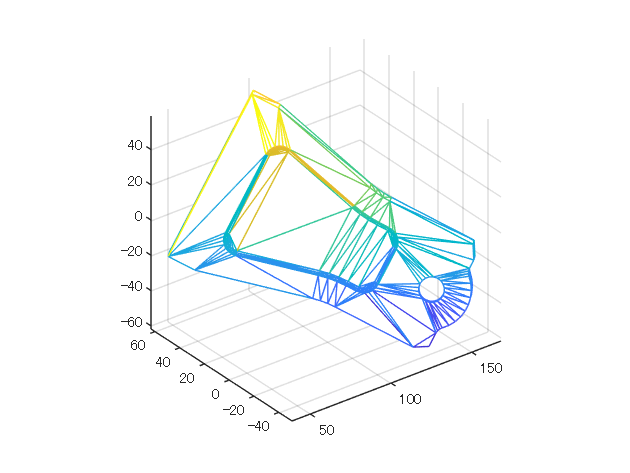

pt = TR.Points;
% モデルの回転
[az,el,~] = cart2sph(1,1,1);
pt1 = rotation(pt,center,-az,-el);
tr = triangulation(TR.ConnectivityList, pt1);
trimesh(tr)
axis("equal")

テストコード

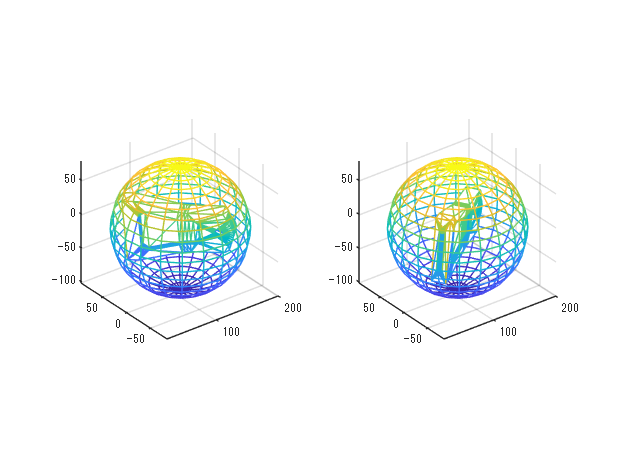

% 別の回転
[az,el,~] = cart2sph(0.8147,0.9058,-0.1270);
pt2 = rotation(pt,center,-az,-el);
tr2 = triangulation(TR.ConnectivityList, pt2);
% 別の回転
[az,el,~] = cart2sph(0.9134,-0.6324,0.0975);
pt3 = rotation(pt,center,-az,-el);
tr3 = triangulation(TR.ConnectivityList, pt3);


subplot(1,2,1);
trimesh(tr2)
hold on
mesh(x*radius+center(1),y*radius+center(2),z*radius+center(3),'FaceColor','none')
hold off
axis("equal")

subplot(1,2,2);
trimesh(tr3)
hold on
mesh(x*radius+center(1),y*radius+center(2),z*radius+center(3),'FaceColor','none')
hold off
axis("equal")

正しく回転ができていれば、2節で表示した球内でモデルが表示されているはずです。

## 5. ラドン変換

4節までの内容をふまえて、全方向からのラドン変換を実装する関数を作成します。

改めて手順を確認すると

- モデルの中心座標と半径を求める

- 1の結果から、x 軸を軸としたラドン変換ができるようにモデルを平行移動する

- 視点データごとにモデルを回転させる

- 回転させたモデルでラドン変換

のようになります。

上記の手順をふまえて、それぞれの視点でラドン変換を行ってください。

それぞれの視点ごとに、1次元配列ができると思うので、それを行要素とする2次元配列を出力してください。

ラドン変換を複数回行うので処理に時間がかかるので注意してください。（長いと数10分とか）

テストコード

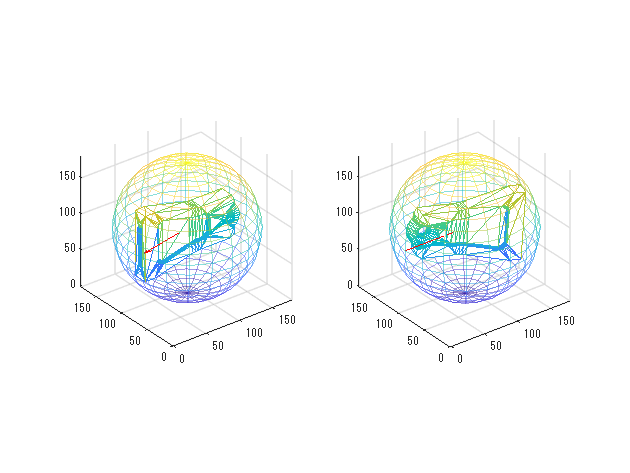

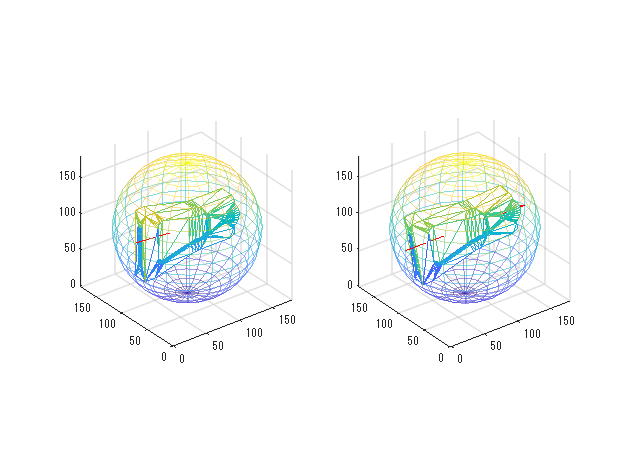

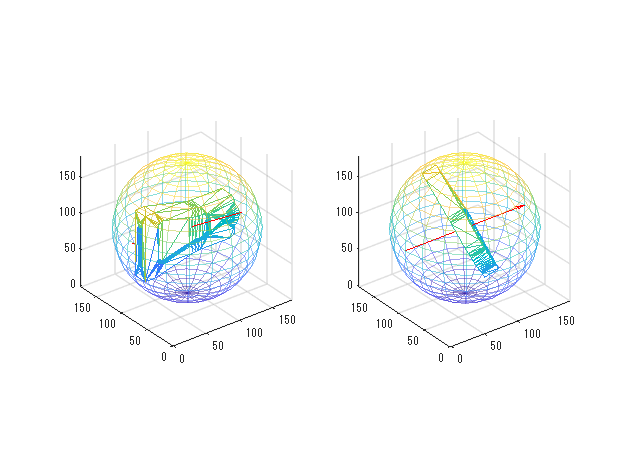

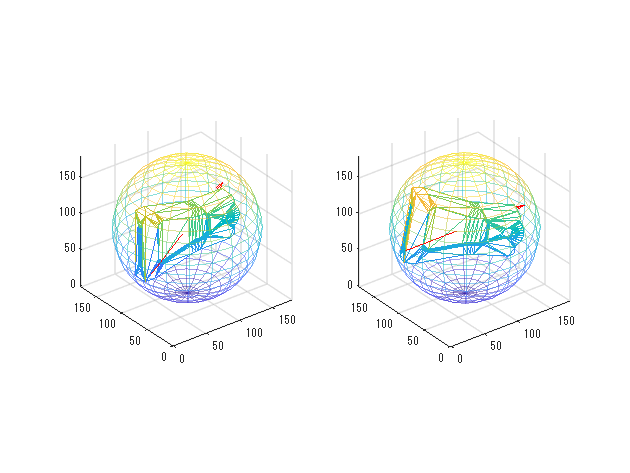

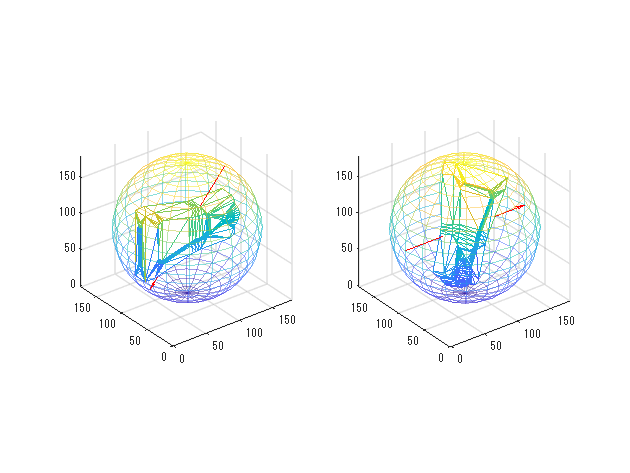

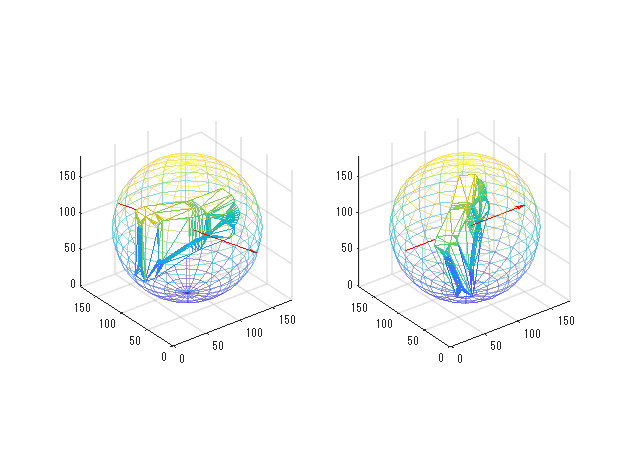

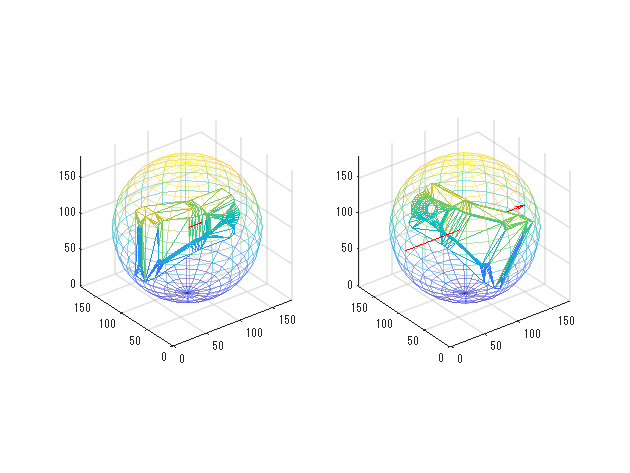

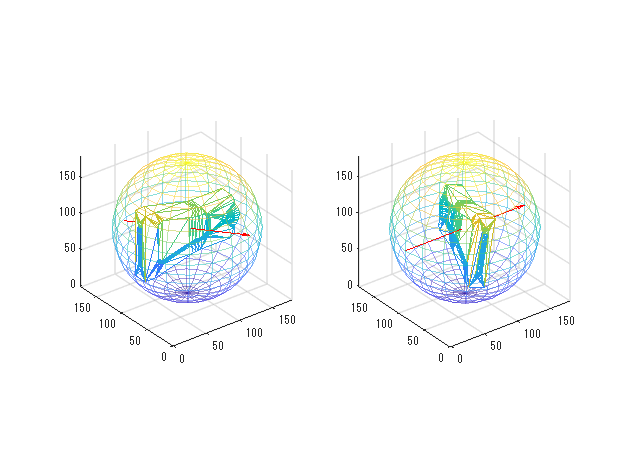

tol = 3e+4;

assert(abs(sum(section(1,:))-1.4540e+5) < tol)
assert(abs(sum(section(30,:))-1.4865e+5) < tol)